# Worksheet 2, Part 1: The Compartmental SIR Model

*Author:* Zachary del Rosario, Fall 2020 (edited Fall 2023)

*Important Note:* Worksheet 2 comes to you in **three parts**; `worksheet2_part1_assignment.mlx`, `worksheet2_part2_assignment.mlx,` and `worksheet2_part3.mlx`

*Learning Objectives:* As a result of working through this notebook, you will learn:

- Fundamental concepts in disease transmission

- An example stock and flow model in the context of [epidemiology](https://en.wikipedia.org/wiki/Epidemiology) (study of disease transmission): the compartmental SIR model

- How to write your own functions to run multiple simulations

- How to run parameter sweeps of your models

- How to use parameter sweeps to help address modeling questions

### Additional Files

Make sure to download these additional files from Canvas and place them in the same folder as this worksheet:

- `action_sir.m`

- `simulate_sir.m`

clear;

## Table Collaboration

While working on this worksheet, we encourage you to work with students at your table (in class) or even across studios (outside class). You can ask your tablemates for help on questions, answer questions that others have, or just compare answers to get a deeper understanding of the worksheet.

To encourage you to collaborate with others, we're asking you to document the folks you worked with. (This way, *we'll know* if you didn't work with anyone....)

*(Write the names of your collaborators here!)*

Jade, Quinn, Rahul

## Disease Transmission

From here onward we're going to (mostly) model the transmission of a disease between persons. While ModSim isn't *just* about disease transmission, we've decided to stick with disease transmission for *most* of the course. **This is because sound modeling requires us to have deep knowledge of the relevant science.** Sticking with this topic for awhile will help you build up some scientific knowledge of disease transmission. And besides: knowledge of how to prevent the spread of disease is an inherently good thing!

To help frame this part of the worksheet we're going to pose (and answer!) the following modeling question:

> "Do disease outbreaks only end once everyone gets infected?"

Let's start by doing some *research* to learn a bit about disease transmission.

### Exercise 1 / 10

Read this (short!) CDC article on "[How Infections Spread](https://www.cdc.gov/infectioncontrol/spread/index.html)." Then think about the progression of a *novel* disease (a disease for which no one has immunity). Answer the questions below.

- What are all of the *states* that an individual can be in, with respect to the new disease? For instance, the initial state that all persons are in should be "uninfected, but with no immunity to the disease."

-  *(List as many states as you can!) *They can be sick with symptoms of an infection, sick without symptoms of an infection, uninfected but vaccinated, previously infected and now with immunity to the disease, or uninfected with no immunity to the disease.

- List as many as you can: the physical *mechanisms* by which a disease can transmit to new people:

-  *(List as many mechanisms as you can!) *Touch (contact between different people), sprays and splashes (coughs/sneezes), inhailation, or sharps injuries (cutting yourself on a used tool that has the disease on it)

- What are some commonalities between the transmission mechanisms you listed above?

-  *(Write your response here) *It involves someone being sick first and people being close together.

- You probably listed *a lot* of states up above. What are the *minimal* states necessary to address the modeling question above?

-  *(Write your response here) *Infected, uninfected with no immunity to the disease, and previously infected with immunity to the disease (including vaccinations since it technically injects the disease into you)

- Of the minimal states you listed above, which ones would have some effect on the number of new infections within a given time period? (It may help to think of "new infections" as a flow, and the "minimal states" you listed as stocks.)

-  *(Write your response here) *Infected and uninfected with no immunity to the disease.

### **Exercise 2 / 10 (Fix It!)**

Recall the question you answered above:

> What are some commonalities between the transmission mechanisms you listed above?

Imagine that, in response to this, a student wrote:

> "I think that the mechanisms are super-similar because they all involve a person being infected coming into some kind of contact with a person who is not infected."

Apply the lessons from the Writing Workshop to improve the provided answer to make it **clear** and **concise**. (Note: Do not change the **meaning** of the answer. Just change the **phrasing**.) Make sure to pay attention to the following **skills**:

- Use active voice

- Cut the fluff

- Use simple vocabulary

Write your updated sentence below, and make sure to note which skills you used.

(*Write your **improved** sentence here*)

All the mechanisms involve an infected person coming into contact with an uninfected person.

(*Write the skills you used to improve the sentence*)

Cut the fluff, active voice

Once you've finished your editing, share your modified sentence with another person at your table. What approach did they take?

They cut the fluff and used more active voice.

### The compartmental SIR Model

Epidemiologists—scientists who study the outbreak and transmission of disease—use compartmental (stock and flow) models to study disease transmission dynamics. One standard model is the *Susceptible-Infected-Recovered* (SIR) model. The following diagram depicts the SIR model:

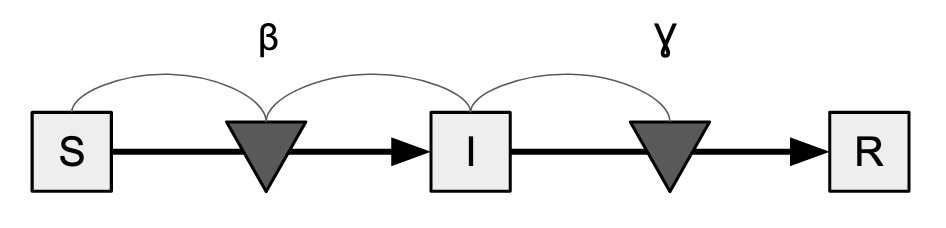

Figure 1. The compartmental SIR model.

Our three stocks are:

- **Susceptible**: The number of persons that could still get infected by the disease

- **Infected**: The number of persons currently infected with the disease, capable of spreading the disease to others

- **Recovered**: The number of persons who have recovered from the disease, no longer capable of infecting others

These three stocks are connected by two flows:

- **Infections**, controlled by the $\beta$ valve. This moves persons from S to I. This flow describes how quickly the disease tends to move through the population. Note that the *information links *(thin curves) tell us that the infection rate also depends on the S and I stocks. This hopefully makes sense: We need a nonzero number of Susceptible people to become infected, and every Infected person has some chance to infected a Susceptible person.

- **Recoveries**, controlled by the $\gamma$ valve. This moves persons from I to R. This flow describes how quickly each infected person tends to recover from the disease. Note that the information links tell us that the recovery rate depends on the I stock only.

As always, this model makes some assumptions about disease progression. *For instance*, the SIR model above assumes that recovered persons cannot become re-infected; this may be a good assumption for a disease like chickenpox, where [reinfection is rare](https://www.ncbi.nlm.nih.gov/pmc/articles/PMC4529600/). It may be a bad assumption for other diseases, such as a virus that tends to mutate and evade prior immunity (e.g., influenza or SARS-CoV-2).

**Important note:** The SIR model is commonly used in epidemology, but it is a *terrible* model for some diseases. For instance, [covid-19 is known to have behavior that violates the assumptions of the compartmental SIR model](https://www.theatlantic.com/health/archive/2020/09/k-overlooked-variable-driving-pandemic/616548/), meaning you *cannot reasonably *use a compartmental SIR model to study the coronavirus pandemic! (However, we will study SARS-CoV-2 in Worksheet 5!)

Despite these limitations, the compartmental SIR is *useful* for investigating many different questions we might have about disease transmission. For instance, we could modify the parameters to represent different scenarios and simulate results to compare the outcomes under these different scenarios.

### **Exercise 3 / 10**

Based on the SIR stock and flow diagram above, could we "play" with the valves (modify the parameter values) to represent public health interventions meant to reduce the rate of spread of the disease? Which valve would we "play" with to represent that change?

- *    (Write your answer here) *The number of infections, $\beta$.

This picture is useful for understanding our model, but before we can start simulating results from our model, we'll need to relate the stock and flow diagram to a set of equations.

## Translating SIR to Equations

The SIR stock and flow diagram gives us a useful picture to reason about the model. However, to implement this model using MATLAB, we need to *translate* this stock and flow diagram into a set of equations. In so doing, we'll gain a better understanding of what the diagram above actually means.

First, let's introduce *state variables* to represent each of the three stocks:


$$S_t = \text{Count of Susceptible persons at time } \,t \\
I_t = \text{Count of Infectious persons at time }\, t \\
R_t = \text{Count of Recovered persons at time }\, t $$


Use this notation to translate the stock and flow diagram above (Figure 1) into an action (a set of equations).

### Exercise 4 / 10

Using what you learned in Worksheet 1, translate Figure 1 into a set of equations that define the action. To make this clearer, define the flow from S to I as $\Delta I_t$, and the flow from I to R as $\Delta R_t$.

*(Write your equations here.)*

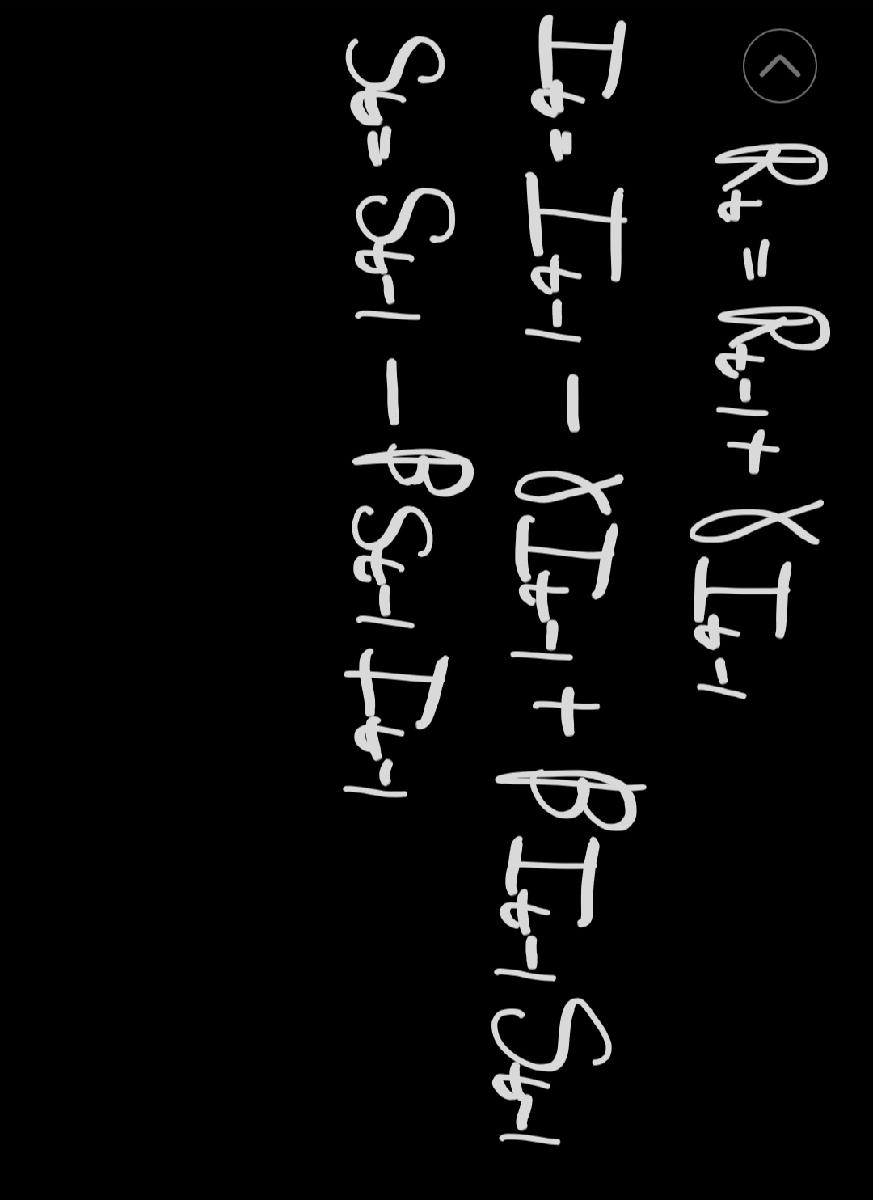

**Compare your equations with someone else at your table. Did you get the same answer?**

The mathematical form of the action helps to highlight some of the other assumptions that the compartmental SIR model makes. The next exercise will help you think those assumptions through.

### **Exercise 5 / 10**

Let's suppose $\beta = 1 / 50, S_1 = 50, I_1 = 1$. What would $\Delta I_1$ be equal to *in our model?* *In reality*, would you expect $\Delta I_1$ to *always* take the same value given $S_1 = 50, I_1 = 1$? Why or why not? What kind of simplifications does this model make?

*Hint:* Are all human beings identical? What about people of different ages?

- *    (What will the value of *$\Delta I_1$ *be? Write your response here)*

- It would be equal to 1.

- *    (Will it always take that value? Write your response here)*

- No, in reality the infection rate might not be accurately represented by a constant changing flow.

## Implementing the SIR Model

In summary, our SIR model evolution equations are:


$$\Delta I_t = \beta \times I_t \times S_t \\
\Delta R_t = \gamma \times I_t \\
S_{t+1} = S_t - \Delta I_t \\
I_{t+1} = I_t + \Delta I_t - \Delta R_t \\
R_{t+1} = R_t + \Delta R_t$$


Like we saw with the models in Worksheet 1, we can implement this model by creating variables s`, i, r` to track the state and running an update function. We're going to take this idea further by making a function for the *action* and a function for the *simulation*.

### Writing Functions

In Worksheet 1 we *used* functions, but now let's learn how to *write* a function! We'll use a function from the previous worksheet to learn about the parts of a function.

There are three main parts to a function, listed here and boxed below for the `action_rabbit_fox` function:

- The function's *signature.* This defines the function's inputs (below, `R_old`, `F_old`, ...), outputs (below, `R_new, F_new`), and name (`action_rabbit_fox)`.

- The function's *documentation*. This does not include executable code, but rather tells the user how to use the function. **All decent and morally-correct functions have documentation. ****It is a mortal sin to write a function without documentation!** *Note:* The `help()` function works not just for built-in MATLAB functions, but also for all properly-documented functions in `.m` files!

- The function's *body*. The body is responsible for computing the outputs; just assign values to the same variables named in the signature and MATLAB will take care of the rest. The body has access to the input values, available as the variables named in the signature.

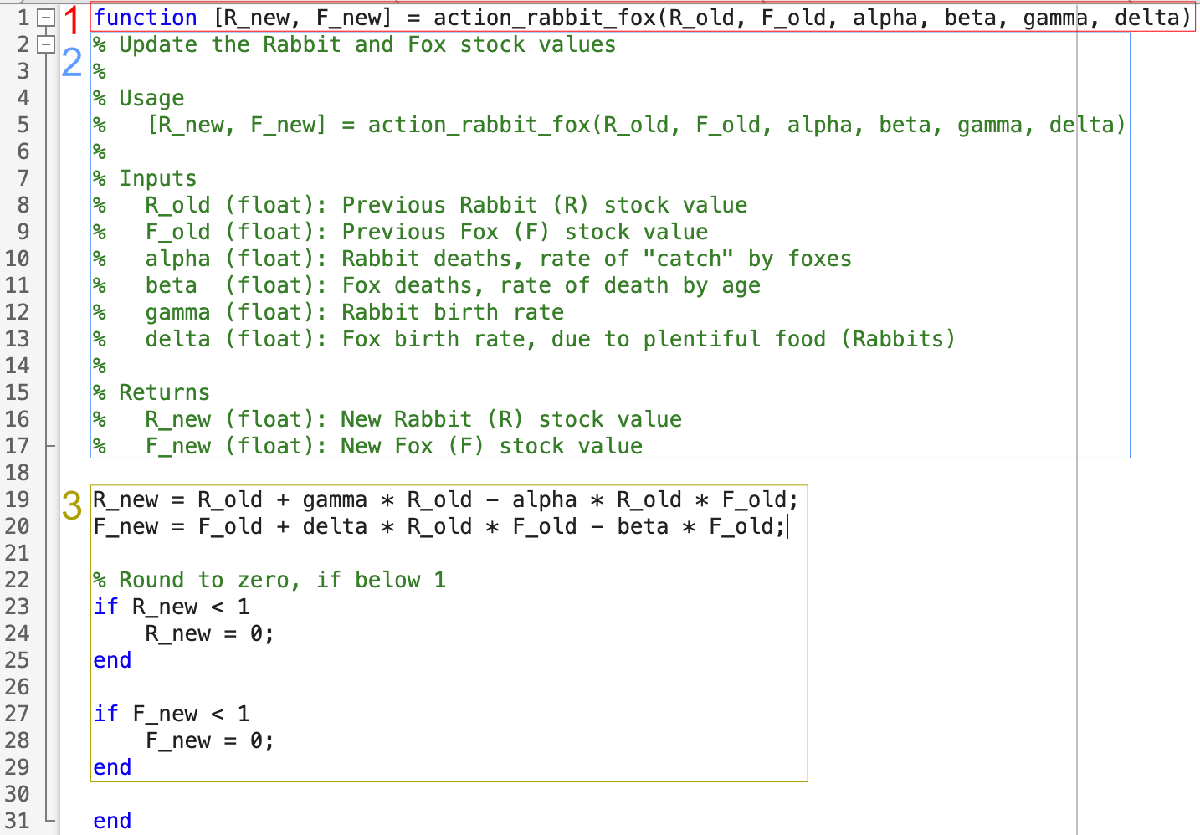

You'll need to learn how to write functions to successfully complete your project work. The next exercise will walk you through this process.

### Exercise 6 / 10

Follow these steps to write your action function:

- Click `New > Function` to create a function file.

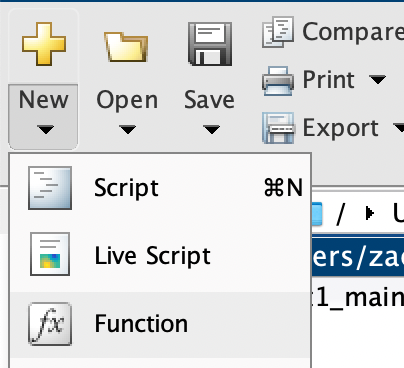

- Change the function signature to the correct form, shown below:

- Implement the SIR update action in your function.

- Save your function file as `myaction_sir.m`, in the **same directory** as this script. Note that getting both the function name and location correct is **required** for MATLAB to be able to find your function. Also, remember that you need to change folders to this script's location!

Once you have finished writing your function, run the code below to check your work.

% TODO: Once you have written myaction_sir(...), run the code here
% to check that your work is correct. You don't need to write any code
% here!

% NOTE: Do not edit this code; use this to check your work
% Check that the function runs
[s_s, i_s, r_s]= myaction_sir(1, 1, 0, 1.0, 1.0);
% Check for correctness
[s_r, i_r, r_r] = action_sir(1, 1, 0, 1.0, 1.0);
assert(s_s == s_r, 'Your s value is incorrect.')
assert(i_s == i_r, 'Your i value is incorrect.')
assert(r_s == r_r, 'Your r value is incorrect.')
disp('Assertions passed')

Assertions passed


The exercise above had you check your function against a *reference implementation*. For the rest of the worksheet though, we can just use my implementations of the action (`action_sir.m`) and simulation loop (`simulate_sir.m`). You'll get started using `action_sir()` in the next exercise.

### **Exercise 7 / 10**

Practice using the action function! Complete the code below to run `action_sir()`. Answer the questions below.

*Hint*: Remember that you can use `help action_sir` in the Command Window to get help, or you can read the source code above to figure out how to call `action_sir()`.

% NOTE: Do not change these initial conditions or parameter values
s_1 = 99;
i_1 =  1;
r_1 =  0;

beta = 1 / 5;
gamma = 1 / 4;

% TODO: Use the function action_sir() to advance the solution
result = myaction_sir(s_1, i_1, r_1, beta, gamma)

result = 79.2000

% result = action_sir(...)

**Questions:** 

- What is the `result` of `action_sir()`? (Numerical value and its meaning)

-  *(Write your response here) *s_n = 79.2. It means that when t = 1 the amount of uninfected people was about 79.

- How many state values does the SIR model have? How many values does `result` contain?

-  *(Write your response here) *It has 3 state values and result contains 1 value.

### Multiple Return Values

You'll find that `result = action_sir()` gives you just one value, but we need values for all of `s, i, r`. To handle this, we can assign all of the *multiple return values* that action_sir`()` provides. To do this we need to provide three variables to "catch" all three outputs. The following code collects all three outputs in `s_n, i_n, r_n`.

[s_n, i_n, r_n] = action_sir(s_1, i_1, r_1, beta, gamma)

s_n = 79.2000

i_n = 20.5500

r_n = 0.2500

That's more like it!

### Implementing the simulation

So far, we've written a `for` loop every time we want to run a simulation. However, re-writing that code is silly; we should just write a function to run this code. The Worksheet 2 folder also includes a `simulate_sir()` function to drive the model. Let's use this simulation function to study the compartmental SIR model.

% Define initial state
% A population of 100 persons, 99 susceptible and 1 infectious
s_1 = 99;
i_1 = 1;
r_1 = 0;

% Let's interpret t to be Weeks. Thus, we have the following parameter
% interpretations:
% Infection rate: Each infected person has a chance to infect 1 susceptible
%                 person out of 50
% Recovery rate: The infection lasts 4 weeks before recovery

beta = 1 / 50; % Infection rate
gamma = 1 / 4; % Recovery rate

With the state and system defined, we can run the simulation and plot its results.

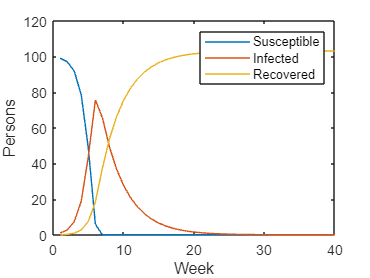

% Run simulation
t_end = 40;
[S, I, R, W] = simulate_sir(s_1, i_1, r_1, beta, gamma, t_end);

% Plot
figure()
plot(W, S, 'DisplayName', 'Susceptible'); hold on
plot(W, I, 'DisplayName', 'Infected')
plot(W, R, 'DisplayName', 'Recovered')

xlabel("Week")
ylabel("Persons")
legend()

### **Exercise 8 / 10**

Simulate the compartmental SIR model with a modified value for $\beta$ to answer the following questions. Assign your simulation results to new variables: `Sn, In, Rn, Wn.`

What would happen if you *decrease* $\beta$? Make a hypothesis about the resulting curves of S, I, and R. Then change $\beta$ to a lower value (at most 1/4th its present value) and run the model again. Did your hypothesis hold?

*Hint:* You can copy and modify the code above to help answer this question.

- *    (Write your hypothesis here) *Less people will get infected over time which means that less people will also recover.

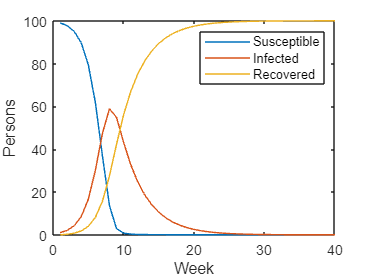

% TODO: Test your hypothesis here
% [Sn, In, Rn, Wn] = ???
beta = 1 / 75; 
gamma = 1 / 4;

t_end = 40;
[Sn, In, Rn, Wn] = simulate_sir(s_1, i_1, r_1, beta, gamma, t_end);

% Plot
figure()
plot(Wn, Sn, 'DisplayName', 'Susceptible'); hold on
plot(Wn, In, 'DisplayName', 'Infected')
plot(Wn, Rn, 'DisplayName', 'Recovered')

xlabel("Week")
ylabel("Persons")
legend()

% NOTE: Do not edit this code; use this to check your work
assert(exist('Sn'), 'You did not assign your simulation results to the correct variables.')
assert(Sn(end) > 0, 'You did not modify beta correctly.')
disp('Assertions passed')

Assertions passed


- *    (Assess your hypothesis here!)*

My hypothesis was correct.

## Metrics and Parameter Sweeps

Let's recall our modeling question for this part of the worksheet:

> (Original Question) "Do disease outbreaks only end once everyone gets infected?"

You should be able to answer this question using the graph you created above! But now that we've answered that question, there's a natural follow-up question we should ask:

> (Refined Question) "How infectious does a disease need to be for everyone to become infected?"

We could *try* to answer this by tweaking $\beta$ and looking at graphs like the one above. However, it would be much more effective to define a *metric* and peform a *parameter sweep*. A metric is a key part of SPAM (state, parameters, action, **metrics**).

A *metric* is a way to summarize a model's results *in a way that helps us answer our modeling question*. For instance, if we were interested in how much of a burden the number of Infected would place on the healthcare system, we might use a metric defined as the peak number of infected individuals:

[I_max, W_max] = max(I)

I_max = 75.6200

W_max = 6

We could plot this on the original infection curve to contextualize the numbers:

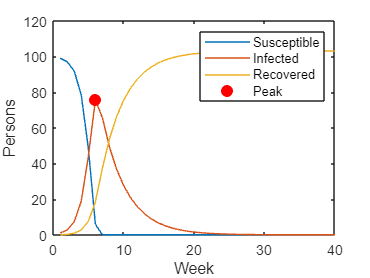

% Plot
figure()
plot(W, S, 'DisplayName', 'Susceptible'); hold on
plot(W, I, 'DisplayName', 'Infected')
plot(W, R, 'DisplayName', 'Recovered')
plot(W_max, I_max, 'r.', 'MarkerSize', 24, 'DisplayName', 'Peak')

xlabel("Week")
ylabel("Persons")
legend()

But the metric itself is useful because it *summarizes* the large amount of data in the full Infected timeseries `I` in terms of a single relevant number.

### Exercise 9 / 10

Choose and compute a metric over the complete timeseries of Susceptible persons `Sn` that is appropriate for the modeling question above (the Refined Question).

% TODO: Compute a metric over the full timeseries of Susceptible persons
% that will help you answer the modeling question.
S_metric = min(Sn)

S_metric = 0.0423


% NOTE: Do not edit this code; use this to check your work
assert(S_metric == Sn(end))
disp('Assertions passed')

Assertions passed


### Parameter Sweeps

Our Refined Question concerns the infectiousness of the disease we're considering. In our model, "infectiousness" is controlled by $\beta$, so we could test this question by tuning beta and observing the changes in the model. However, it would be silly to randomly change $\beta$ and just "remember" what happened to the model for different values. It would be a far better idea to use our carefully-chosen metric and *sweep* over many values of $\beta$, and visualize the results.

For instance, if we were interested in healthcare system overload, we could use the "max" metric described above. We should then pick a range of $\beta$ values to test. The MATLAB function `linspace()` gives us `lin`early `space`d values between `start` and `end` values, using a specified number of points.

%                   start, end,   n_points
Beta_all = linspace(0.001, 0.015, 100)

Beta_all =     0.0010    0.0011    0.0013    0.0014    0.0016    0.0017    0.0018    0.0020    0.0021    0.0023    0.0024    0.0026    0.0027    0.0028    0.0030    0.0031    0.0033    0.0034    0.0035    0.0037    0.0038    0.0040    0.0041    0.0043    0.0044    0.0045    0.0047    0.0048    0.0050    0.0051    0.0052    0.0054    0.0055    0.0057    0.0058    0.0059    0.0061    0.0062    0.0064    0.0065    0.0067    0.0068    0.0069    0.0071    0.0072    0.0074    0.0075    0.0076    0.0078    0.0079


We can then run a simulation for each value of beta, use the metric to summarize the results, and record the metric value for each simulation.

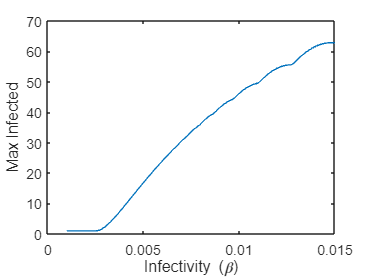

% Reserve space for the resulting metric values
S_metric = zeros(size(Beta_all));

% Loop over all beta values
for i = 1 : length(Beta_all)
    % Simulate with the desired beta
    beta_temp = Beta_all(i);
    [S, I, R, W] = simulate_sir(s_1, i_1, r_1, beta_temp, gamma, t_end);
    % Compute and store the metric value
    S_metric(i) = max(I);
end

% Visualize the results
figure()
plot(Beta_all, S_metric)
xlabel('Infectivity (\beta)')
ylabel('Max Infected')

Let's apply these ideas to our own modeling question.

### Exercise 10 / 10

Use the metric you defined above to perform a parameter sweep over $\beta$. Use the same range of values stored in `Beta_all`. Answer the questions below.

% TODO: Do a parameter sweep over Beta_all
S_metric = zeros(size(Beta_all));

% Loop over all beta values
for i = 1 : length(Beta_all)
    % Simulate with the desired beta
    beta_temp = Beta_all(i);
    [S, I, R, W] = simulate_sir(s_1, i_1, r_1, beta_temp, gamma, t_end);
    % Compute and store the metric value
    S_metric(i) = max(I);
end

% Visualize the results
figure()
plot(Beta_all, S_metric)
xlabel('Infectivity (\beta)')
ylabel('Max Infected')

- How infectious does a disease need to be for everyone to become infected?

-  *(Write your response here)*

It needs to have a beta value of at least 0.03

**Compare your result with someone else at your table. Did you get the same answer?**

## Looking Forward

In the next notebook we'll use this SIR model in conjunction with *data* to *choose parameters*. This will help us to better anchor our model in reality.